Calculates the normalized passive force in muscle fibers with respect to the passive force-length relationship (applies to all muscles in OpenSim musckuloskeletal model)

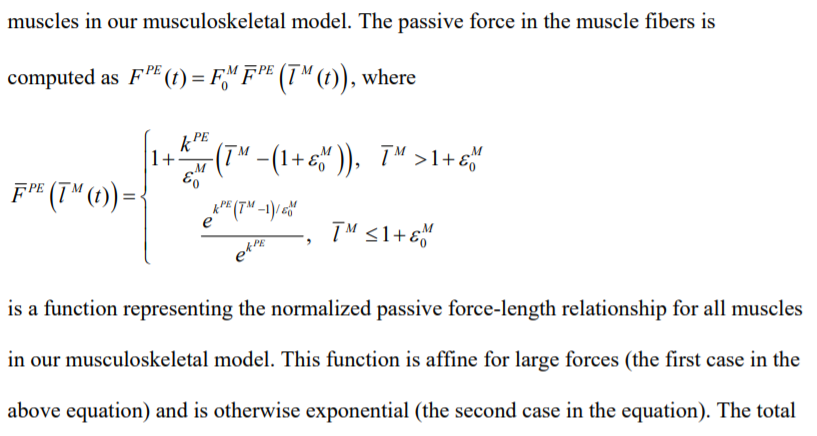


$$\overset{~}{l}$$


function F_PE = Thelen2003_Passive_Force_Length(fib_len_norm)
    k_PE = 5; % an exponential shape factor for the passive force-length relationship
    eM_0 = 0.6; % passive muscle strain due to maximum isometric force
    F_PE = zeros(size(fib_len_norm));
    for i = 1:length(fib_len_norm)
        lM_norm = fib_len_norm(i);
        if lM_norm > 1
            t5 = exp(k_PE * (lM_norm - 1) / eM_0);
            t7 = exp(k_PE);
%             F_PE(i) = 1 + k_PE/eM_0 * (lM - (1 + eM_0));
            F_PE(i) = (t5 - 1) / (t7 - 1);
        elseif lM_norm <= 1
%             F_PE(i) = exp(k_PE * (lM - 1) / eM_0) / exp(k_PE);
            F_PE(i) = 0;
        end
    end        
end